    COURSE: PCA and multivariate neural signal processing

   SECTION: Source separation with GED

     VIDEO: GED in a simple example

Instructor: sincxpress.com

% a clear MATLAB workspace is a clear mental workspace
close all; clear, clc


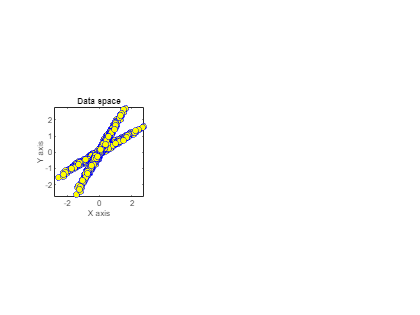

% generate data
x = [ randn(1000,1) .05*randn(1000,1) ];

% rotation matrix
th = -pi/6;
R1 = [ cos(th) -sin(th); sin(th) cos(th) ];
th = -pi/3;
R2 = [ cos(th) -sin(th); sin(th) cos(th) ];

% rotate data
y = [ x*R1 ; x*R2 ];


figure(1), clf
subplot(131)
plot(y(:,1),y(:,2),'bo','markerfacecolor','y')
axis([-1 1 -1 1]*max(abs(y(:))))
xlabel('X axis'), ylabel('Y axis')
axis square
title('Data space')

## run PCA

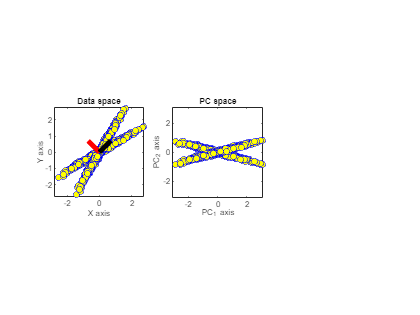

% mean-center
y = bsxfun(@minus,y,mean(y,1));

% eigendecomposition of covariance matrix
[evecsPCA,evalsPCA] = eig( (y'*y) / length(y) );

% plot eigenvectors
hold on
plot([0 evecsPCA(1,1)],[0 evecsPCA(2,1)],'r','linew',5)
plot([0 evecsPCA(1,2)],[0 evecsPCA(2,2)],'k','linew',5)

%% plot the data in PC space

comps = evecsPCA'*y';

subplot(132)
plot(comps(2,:),comps(1,:),'bo','markerfacecolor','y')
axis([-1 1 -1 1]*max(abs(comps(:))))
xlabel('PC_1 axis'), ylabel('PC_2 axis')
axis square
title('PC space')

## GED

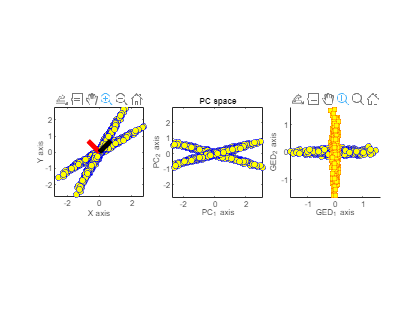



% covariance matrices
S = cov(y(1:1000,:));
R = cov(y(1001:end,:));

% GED with optional scaling
%%% try without the normalization!
[evecsGED,D] = eig(S,R);
evecsGED = bsxfun(@rdivide,evecsGED,sqrt(sum(evecsGED.^2,1)));

% component time series
comps = evecsGED'*y';

subplot(133), cla, hold on
plot(comps(2,1:1000),comps(1,1:1000),'bo','markerfacecolor','y')
plot(comps(2,1001:end),comps(1,1001:end),'rs','markerfacecolor','y')
axis([-1 1 -1 1]*max(abs(comps(:))))
xlabel('GED_1 axis'), ylabel('GED_2 axis')
axis square
title('GED space')
zoom on